clc; clear;


data = importdata("Samlet Log data  19-05-2023 12.35.19 20% sukker vand.txt");

CP = py.importlib.import_module("CoolProp.CoolProp");

# Behandlet data

P1 = find(data.textdata(1,2:end) == "P1 Tryk")

P1 = 15

H1 = find(data.textdata(1,2:end) == "P1 Enthalpy")

H1 = 16


P2 = find(data.textdata(1,2:end) == "P2 Tryk")

P2 = 20

H2 = find(data.textdata(1,2:end) == "P2 Enthalpy")

H2 = 21


P3 = find(data.textdata(1,2:end) == "P3 Tryk")

P3 = 25

H3 = find(data.textdata(1,2:end) == "P3 Enthalpy")

H3 = 26


P4 = find(data.textdata(1,2:end) == "P4 Tryk")

P4 = 30

H4 = find(data.textdata(1,2:end) == "P4 Enthalpy")

H4 = 31


start = 10;

p1 = data.data(start:end, P1);
h1 = data.data(start:end, H1);

p2 = data.data(start:end, P2);
h2 = data.data(start:end, H2);

p3 = data.data(start:end, P3);
h3 = data.data(start:end, H3);

p4 = data.data(start:end, P4);
h4 = data.data(start:end, H4);



ps = data.data(start:end, [P1,P2,P3,P4]);
hs = data.data(start:end, [H1,H2,H3,H4]);

mean_ps = mean(ps)

mean_ps =     0.9021    7.3009    7.3009    0.9021


mean_hs = mean(hs)

mean_hs =   378.1161  427.6037  238.9842  238.9842


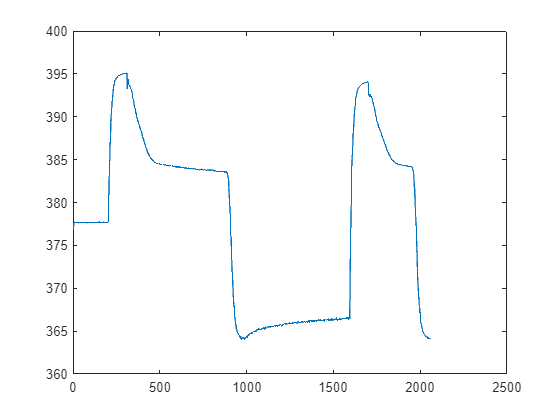


figure
plot(h1)

mean(h1(500:850))

ans = 383.9969

hlin1 = linspace(mean_hs(1),mean_hs(2));
hlin2 = linspace(mean_hs(2),mean_hs(3));
hlin3 = linspace(mean_hs(3),mean_hs(4));
hlin4 = linspace(mean_hs(4),mean_hs(1));
hs_test = [hlin1,hlin2,hlin3,hlin4];

plin1 = linspace(mean_ps(1),mean_ps(2));
plin2 = linspace(mean_ps(2),mean_ps(3));
plin3 = linspace(mean_ps(3),mean_ps(4));
plin4 = linspace(mean_ps(4),mean_ps(1));
pps_test = [plin1,plin2,plin3,plin4]+1;


# Temps

Tbrine = find(data.textdata(1,2:end) == "Brinetemperatur")

Tbrine = 4

Trum = find(data.textdata(1,2:end) == "Rumtemperatur")

Trum = 2



Tbrine = mean(data.data(start:end-1, Tbrine))

Tbrine = -9.9203

Trum = mean(data.data(start:end,Trum))

Trum = 24.0529


T_komp = find(data.textdata(1,2:end) == "Temperaturen efter fordamper")

T_komp = 6

T_kond = find(data.textdata(1,2:end) == "Temperatur efter kompressor")

T_kond = 10

T_EPV = find(data.textdata(1,2:end) == "Temperatur efter kondensator ")

T_EPV = 11

T_fordamp = find(data.textdata(1,2:end) == "Temperatur efter EPV")

T_fordamp = 9


T1 = min(data.data(start:end-start, T_komp))

T1 = -14.5698

T2 = min(data.data(start:end-start, T_kond))

T2 = 24.6201

T3 = min(data.data(start:end-start, T_EPV))

T3 = 23.8362

T4 = min(data.data(start:end-start, T_fordamp))

T4 = -27.2031

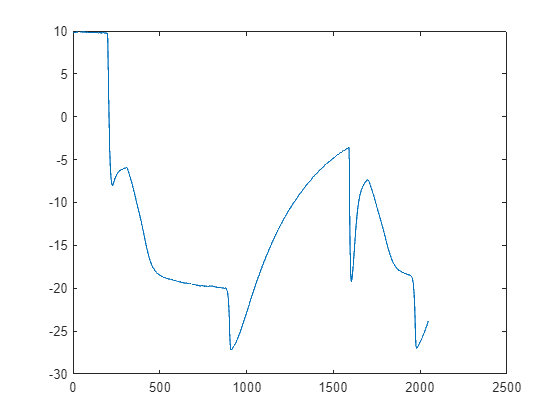



plot(data.data(start:end-start, T_fordamp))

# Teoretisk data

% Kølemiddel
ps = 100;
Tfrys = 0;
Tkog = 1200;
middel = "R134a";

% for R134a
Pmin = CP.PropsSI("P","T",170, "Q", 0, middel)

Pmin = 396.1679

Pmax = CP.PropsSI("P","T", 374, "Q", 1, middel)

Pmax = 4.0421e+06

Plin = linspace(Pmin, Pmax, ps);


Tsat_l = zeros(size(Plin));

for i = 1:ps-1
    Tsat_l(i) = CP.PropsSI("T", "P", Plin(i), "Q", 0, middel);
end

hl = zeros(size(Plin));
hg = zeros(size(Plin));
sl = zeros(size(Plin));
sg = zeros(size(Plin));

for j = 1:ps-1
    hl(j) = CP.PropsSI("H","P",Plin(j), "Q", 0, middel);
    hg(j) = CP.PropsSI("H","P",Plin(j), "Q", 1, middel);
    sl(j) = CP.PropsSI("S","P",Plin(j), "Q", 0, middel);
    sg(j) = CP.PropsSI("S","P",Plin(j), "Q", 1, middel);
end


% Uden tab

h1 = 389428;
p1 = 1.33e5;

h2 = 467171;
p2 = 8.868*1e5;

h3 = 241463;
p3 = p2;

h4 = h3;
p4 = p1;

%til plot

hlin1 = linspace(h1,h2,ps-1);
hlin2 = linspace(h2,h3,ps-1);
hlin3 = linspace(h3,h4,ps-1);
hlin4 = linspace(h4,h1,ps-1);
hs = [hlin1,hlin2,hlin3,hlin4];

plin1 = linspace(p1,p2,ps-1);
plin2 = linspace(p2,p3,ps-1);
plin3 = linspace(p3,p4,ps-1);
plin4 = linspace(p4,p1,ps-1);
pps = [plin1,plin2,plin3,plin4]/1e5;

Tr134a = zeros(size(pps));


for k = 1:length(pps)
    Tr134a(k) = CP.PropsSI("T","H",hs(k),"P",pps(k)*1e5, middel);
end
Tr134a;
Trs = Tr134a-273.15;


% Fra opgave

htab1 = 389428;
ptab1 = 1.33e5;

htab2 = 467171;
ptab2 = 8.868e5;

htab3 = 236622;
ptab3 = 8.068e5;

htab4 = htab3;
ptab4 = 1.65e5;

%til plot

hlintab1 = linspace(htab1,htab2,ps-1);
hlintab2 = linspace(htab2,htab3,ps-1);
hlintab3 = linspace(htab3,htab4,ps-1);
hlintab4 = linspace(htab4,htab1,ps-1);
hs_tab = [hlintab1,hlintab2,hlintab3,hlintab4];

plintab1 = linspace(ptab1,ptab2,ps-1);
plintab2 = linspace(ptab2,ptab3,ps-1);
plintab3 = linspace(ptab3,ptab4,ps-1);
plintab4 = linspace(ptab4,ptab1,ps-1);
pps_tab = [plintab1,plintab2,plintab3,plintab4]/1e5;

Tr134a_tab = zeros(size(pps));


for k = 1:length(pps)
    Tr134a_tab(k) = CP.PropsSI("T","H",hs_tab(k),"P",pps_tab(k)*1e5, middel);
end
Tr134a;
Trs_tab = Tr134a_tab-273.15;


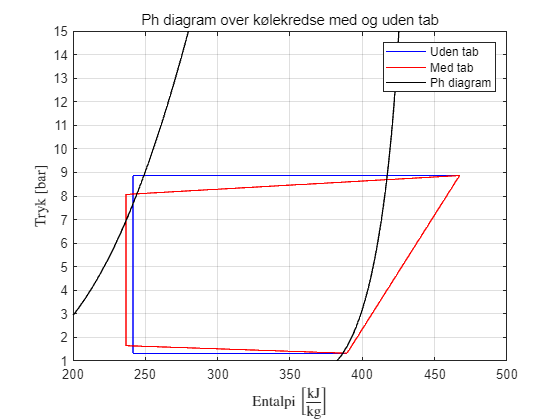


figure

% Kølekreds uden tab
plot([hlin1/1e3,hlin2/1e3,hlin3/1e3,hlin4/1e3],[plin1/1e5,plin2/1e5,plin3/1e5,plin4/1e5],"b")

xlim([2,5]*1e2)
ylim([1,15])
yticks(1:1:15)


grid("on")

hold on

% Data fra faktiske kølekreds
%plot(hs_test,pps_test)

% Kølekreds med tab
plot([hlintab1/1e3,hlintab2/1e3,hlintab3/1e3,hlintab4/1e3],[plintab1/1e5,plintab2/1e5,plintab3/1e5,plintab4/1e5],"r")

% PH diagram (ikke log)
plot(hl(1,1:end-1)/1e3,Plin(1,1:end-1)/1e5,"k")
plot(hg(1,1:end-1)/1e3, Plin(1,1:end-1)/1e5,"k")

title("Ph diagram over kølekredse med og uden tab","FontWeight","normal")
ylabel("Tryk [bar]","Interpreter","latex")
xlabel("Entalpi $\left[\mathrm{\frac{kJ}{kg}}\right]$","Interpreter","latex")

legend("Uden tab","Med tab","Ph diagram","location","northeast")

hold off